# NFLの対戦回数を図示する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

対戦データおよびチーム一覧を読み込む

tbl_results=readtable("../data/NFLResults20232024.xlsx",'sheet','result');
tbl_teams=readtable('../data/NFLResults20232024.xlsx','Sheet','teams');

前処理

teamNames=unique([tbl_results.Winner_tie;tbl_results.Loser_tie]);
tbl_results.Winner_tie=categorical(tbl_results.Winner_tie,teamNames);
tbl_results.Loser_tie=categorical(tbl_results.Loser_tie,teamNames);
tbl_results.At=categorical(tbl_results.At);
tbl_teams.TeamName=categorical(tbl_teams.TeamName,teamNames);
tbl_teams.Conference=categorical(tbl_teams.Conference);
tbl_teams.Division=categorical(tbl_teams.Division);

チーム数のサマリ

summary(tbl_teams)

Variables:

    SeasonStr: 32×1 cell array of character vectors

    SeasonStartYear: 32×1 double

        Values:

            Min         2023  
            Median      2023  
            Max         2023  

    TeamName: 32×1 categorical

        Values:

            Arizona Cardinals           1    
            Atlanta Falcons             1    
            Baltimore Ravens            1    
            Buffalo Bills               1    
            Carolina Panthers           1    
            Chicago Bears               1    
            Cincinnati Bengals          1    
            Cleveland Browns            1    
            Dallas Cowboys              1    
            Denver Broncos              1    
            Detroit Lions               1    
            Green Bay Packers           1    
            Houston Texans              1    
            Indianapolis Colts          1    
            Jacksonville Jaguars        1    


レギュラーシーズンの試合のみ抽出する

ind = tbl_results.isRegular==1;
tbl_results_tmp=tbl_results(ind,:);

試合数のサマリ

summary(tbl_results_tmp)

Variables:

    Week: 272×1 double

        Values:

            Min           1   
            Median      9.5   
            Max          18   

    Day: 272×1 cell array of character vectors

    Date: 272×1 datetime

        Values:

            Min       2023/09/07 00:00:00
            Median    2023/11/07 12:00:00
            Max       2024/01/07 00:00:00

    Time: 272×1 cell array of character vectors

    Winner_tie: 272×1 categorical

        Values:

            Arizona Cardinals            4   
            Atlanta Falcons              7   
            Baltimore Ravens            13   
            Buffalo Bills               11   
            Carolina Panthers            2   
            Chicago Bears                7   
            Cincinnati Bengals           9   
            Cleveland Browns            11   
            Dallas Cowboys              12   
            Denver Broncos         

試合数を集計する．(ホーム，アウェー)で試合数を格納する変数matchCountsを用意する

matchCounts=zeros(size(tbl_teams,1));
for n1=1:size(tbl_results_tmp,1)
    if tbl_results_tmp.At(n1)=='@'
        TeamANum=find(tbl_teams.TeamName==tbl_results_tmp.Loser_tie(n1));
        TeamBNum=find(tbl_teams.TeamName==tbl_results_tmp.Winner_tie(n1));
    else
        TeamANum=find(tbl_teams.TeamName==tbl_results_tmp.Winner_tie(n1));
        TeamBNum=find(tbl_teams.TeamName==tbl_results_tmp.Loser_tie(n1));
    end
    matchCounts(TeamANum, TeamBNum)=matchCounts(TeamANum, TeamBNum)+1;
end

imagesc関数で数値を色として表示する．

colorbar関数は色と数値の対応を示す棒を表示する関数(デフォルトでは右側)

figure
imagesc(matchCounts);
cmap=colormap(gca);
colormap(cmap([1,end],:));
colorbar;colorbar;
set(gca,'fontname','メイリオ');
axis square;
xticks(1:size(tbl_teams,1));
yticks(1:size(tbl_teams,1));
xticklabels(tbl_teams.Abb);
yticklabels(tbl_teams.Abb);
ylabel('ホーム');
xlabel('アウェー');
title('NFL2023-2024レギュラーシーズン試合数')

Divisionが変化する場所に線を引く

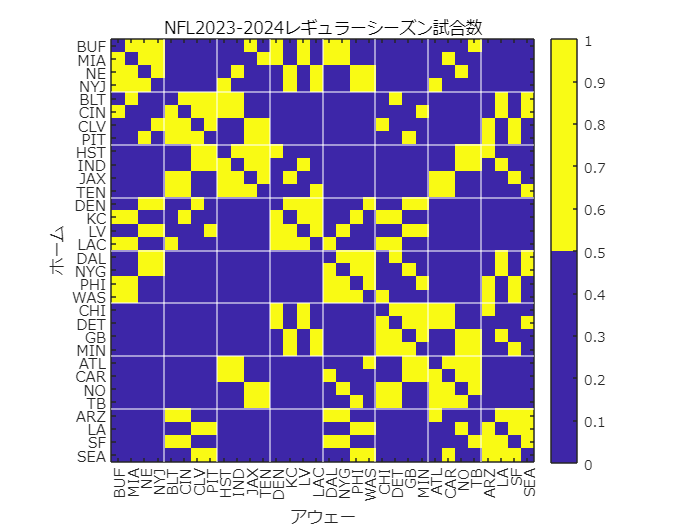

for n1=2:size(tbl_teams,1)-1
    if tbl_teams.Division(n1)~=tbl_teams.Division(n1-1)
        xline(n1-0.5,'w');
        yline(n1-0.5,'w');
    end
end
exportgraphics(gcf,'fig_NFLMatchCounts.pdf')

チームごとに対戦回数をわかりやすく

figure
imagesc(matchCounts+matchCounts');
cmap=colormap(gca);
ind=round(linspace(1,size(cmap,1),3));
colormap(cmap(ind,:));
colorbar;colorbar;
set(gca,'fontname','メイリオ');
axis square;
xticks(1:size(tbl_teams,1));
yticks(1:size(tbl_teams,1));
xticklabels(tbl_teams.Abb);
yticklabels(tbl_teams.Abb);
title('NFL2023-2024レギュラーシーズン試合数')
ylabel('チーム');
xlabel('対戦相手');

Divisionが変化する場所に線を引く

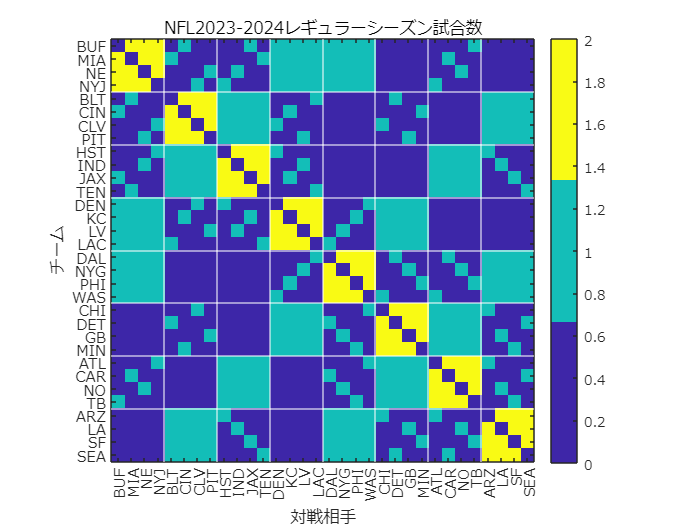

for n1=2:size(tbl_teams,1)-1
    if tbl_teams.Division(n1)~=tbl_teams.Division(n1-1)
        xline(n1-0.5,'w');
        yline(n1-0.5,'w');
    end
end
exportgraphics(gcf,'fig_NFLMatchCountsByTeam.pdf')